## Question 1

warning off; close all; clc;

% Having saved the unit step response of the system from the Simulink Run,

fprintf(">>> Having saved the unit step response of the system from the Simulink Run,\n")

>>> Having saved the unit step response of the system from the Simulink Run,


fprintf("    the data could fetched via:\n")

    the data could fetched via:


fprintf("------------------------------------------------------------------------------")

------------------------------------------------------------------------------

fprintf("                            stepResp = step_resp.Data;\n")

                            stepResp = step_resp.Data;


fprintf("------------------------------------------------------------------------------")

------------------------------------------------------------------------------

stepResp = step_resp.Data;

### >>> 1.1 - Proper Sampling Time

fprintf(">>> The proper sample time for the available system could be obtained by calculating\n")

>>> The proper sample time for the available system could be obtained by calculating


fprintf("    the area between the step response of the system and the constant line with the")

    the area between the step response of the system and the constant line with the

fprintf("    value of steady state response.")

    value of steady state response.


ys = mean(stepResp(floor(length(stepResp))/10:end));

summation = 0;
for index=1:length(stepResp)
    summation = summation + (ys - stepResp(index));
end
summation = summation/ys;

proper_Ts = summation/10;

fprintf("    Hence, the proper sampling time (Ts) = 2")

    Hence, the proper sampling time (Ts) = 2

proper_Ts = 2;

### >>> 1.2 - Input/Output Generation

>>> Generate a signal with the length of 1000 in PRBS format. Acoordingly, time span vector must be generated and the `input_signal` matrix is formed to be loaded in Simulink model.

N = 1000;  
amplitude = 1;

prbs_signal = transpose(amplitude * prbs(5, N));
tspan = transpose(0:proper_Ts:N*proper_Ts-1);
input_signal = [tspan prbs_signal];

    The generated PRBS signal is shown in the following figure.

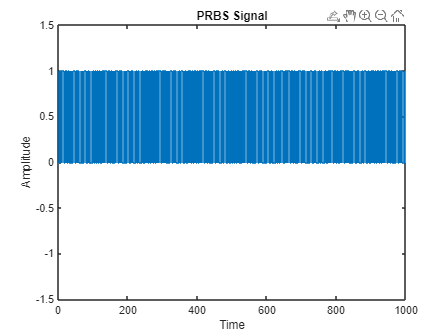

figure(1);
stairs(prbs_signal);
xlabel('Time');
ylabel('Amplitude');
title('PRBS Signal');
ylim([-1.5, 1.5]);

>>> Having run the Simulink model with the generated input signal, the output signal must be read in the script using:

       `y_out = y_out.Data(1:end-1);`

y_out = y_out.Data(1:end-1);

### >>> 1.3 - ARX model - degree of 1 to 10

>>> The sought information are being reported in the following except for the covariance matrix, since its size gets bigger and bigger by the degree increment. So in case you want to check it out, please run the code manually and fetch its value at each iteration.

fprintf("=====================Degree Extraction=======================\n")

=====================Degree Extraction=======================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
for degree=1:1:10
    na = degree;
    nb = degree;
    p = na + nb;

    U = arx_U_builder(na,nb,prbs_signal,y_out);

    theta_hat = inv(U'*U)*U'*y_out;
    y_hat = U*theta_hat;
    
    t = (step_resp.TimeInfo.Start:proper_Ts:step_resp.TimeInfo.End);

    [r2_arx, mse_arx] = rSQR(y_out, y_hat);

    error = y_out - y_hat;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end
    variance = S_hat/(N-p);

    covariance = variance*inv(U'*U);

    detUTU = det(U'*U);
    R2s = [R2s; r2_arx];
    MSEs = [MSEs; mse_arx];
    dets = [dets; detUTU];
    vars = [vars; variance];
%     covs = [covs; covariance];
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | det(UT.U)=%f | var=%f \n", degree, r2_arx, mse_arx, detUTU, variance)
    fprintf("-------------------------------------------------------------\n")
end

>>> Degree = 1 : R2=0.854735 | MSE=0.703615 | det(UT.U)=24888679.879529 | var=0.705025 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.864654 | MSE=0.655571 | det(UT.U)=4714768037060.724609 | var=0.658204 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.872951 | MSE=0.615380 | det(UT.U)=825227572548896384.000000 | var=0.619094 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.930552 | MSE=0.336381 | det(UT.U)=134399249391961774227456.000000 | var=0.339094 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.992569 | MSE=0.035991 | det(UT.U)=11766772605821848745257467904.000000 | var=0.036355 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.993220 | MSE=0.032842 | det(UT.U)=109943778176410353379711685492736.000000 | var=0.033241 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.994593 | MSE=0.026189 | det(UT.U)=936125948527886606373888097756643328.000000 | var=0.026560 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.996743 | MSE=0.015778 | det(UT.U)=6332024679739567099688321680302946648064.000000 | var=0.016035 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.997499 | MSE=0.012115 | det(UT.U)=25681222759067751382086380803033003823464448.000000 | var=0.012337 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.998046 | MSE=0.009467 | det(UT.U)=79780865716172772981769170539774081208722391040.000000 | var=0.009660 


-------------------------------------------------------------


fprintf("=================================================================\n")

>>> Also, note that the dterminant value of the `U'*U` matrix is increased wildly as the testing degree is being added up.

### >>> 1.4 - Bar Plots

####          1.4.1 Based on R2

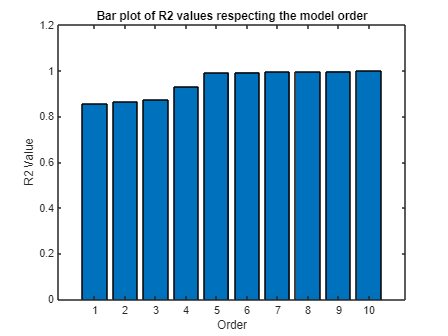

figure(2);
bar(1:1:10, R2s)
title("Bar plot of R2 values respecting the model order")
ylim([0,1.2])
xlabel("Order")
ylabel("R2 Value")

####     1.4.2 Based on variance

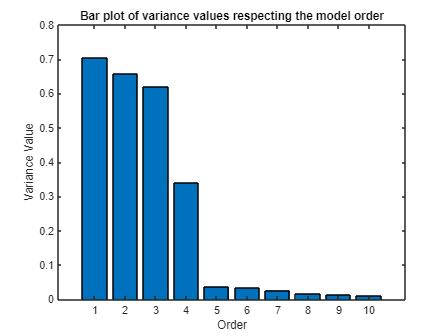

figure(3);
bar(1:1:10, vars)
% ylim([0,1])
title("Bar plot of variance values respecting the model order")
xlabel("Order")
ylabel("Variance Value")

####     1.4.3 Based on MSE

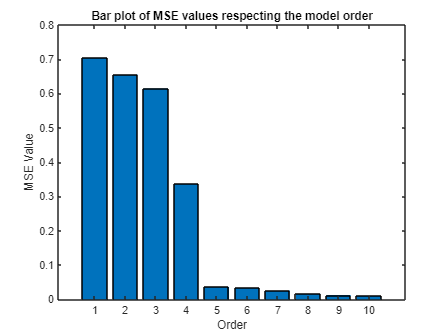

figure(4);
bar(1:1:10, MSEs)
% ylim([0,1])
title("Bar plot of MSE values respecting the model order")
xlabel("Order")
ylabel("MSE Value")

####     1.4.4 Based on determinant

>>> Since the determinant value are increasing rapidlly, plotting the values won't provide any suitable visualization of the story.

### >>> 1.5 - System Order based on R2 values

>>> The minimum accepted value for thr R2 matric is reported as 0.9025.

       So exploring the stored values from the previous section from order of 1 to 10 demonstrates that:

R2_accuracy_level = 0.9025;

[maxR2, maxR2Index] = max(R2s);

degree_based_on_R2 = maxR2Index;

first_acceptable_degree_based_on_R2 = min(find(R2s>R2_accuracy_level));

fprintf("===========================================================================================\n")

fprintf(">>> with respect to R2: Although the estimation starts to be accurate enough from the degree of %d,\n    the best results are obtained in degree of %d.\n", first_acceptable_degree_based_on_R2, degree_based_on_R2)

>>> with respect to R2: Although the estimation starts to be accurate enough from the degree of 4,
    the best results are obtained in degree of 10.


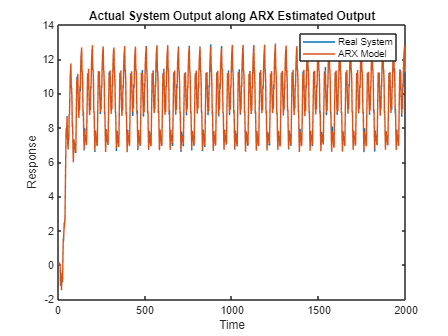

na = degree_based_on_R2;
nb = degree_based_on_R2;
p = na + nb;

U = arx_U_builder(na,nb,prbs_signal,y_out);

theta_hat = inv(U'*U)*U'*y_out;
y_hat = U*theta_hat;

t = (step_resp.TimeInfo.Start:proper_Ts:step_resp.TimeInfo.End);

figure(5)
plot(tspan,y_out,tspan,y_hat)
title("Actual System Output along ARX Estimated Output")
xlabel("Time")
ylabel("Response")
legend('Real System','ARX Model')

### >>> 1.6 - System Order based on MSE values

>>> The maximum accepted value for the MSE matric is taken as 0.1.

       So exploring the stored values from the previous section from order of 1 to 10 demonstrates that:

mse_accuracy_level = 0.1;

[minMSE, minMSEIndex] = min(MSEs);

degree_based_on_MSE = minMSEIndex;

first_acceptable_degree_based_on_MSE = min(find(MSEs<mse_accuracy_level));

fprintf("===========================================================================================\n")

fprintf(">>> with respect to MSE: Although the estimation starts to be accurate enough from the degree of %d,\n    the best results are obtained in degree of %d.\n", first_acceptable_degree_based_on_MSE, degree_based_on_MSE)

>>> with respect to MSE: Although the estimation starts to be accurate enough from the degree of 5,
    the best results are obtained in degree of 10.


na = degree_based_on_MSE;
nb = degree_based_on_MSE;
p = na + nb;

U = arx_U_builder(na,nb,prbs_signal,y_out);

theta_hat = inv(U'*U)*U'*y_out;
y_hat = U*theta_hat;

t = (step_resp.TimeInfo.Start:proper_Ts:step_resp.TimeInfo.End);

figure(6)
plot(tspan,y_out,tspan,y_hat)
title("Actual System Output along ARX Estimated Output")
xlabel("Time")
ylabel("Response")
legend('Real System','ARX Model')

### >>> 1.7 - System Order based on Variance values

>>> The maximum accepted value for the Variance matric is taken as 0.1.

       So exploring the stored values from the previous section from order of 1 to 10 demonstrates that:

var_accuracy_level = 0.1;

[minVar, minVarIndex] = min(vars);

degree_based_on_Var = minVarIndex;

first_acceptable_degree_based_on_Var = min(find(vars<var_accuracy_level));

fprintf("===========================================================================================\n")

fprintf(">>> with respect to Variance: Although the estimation starts to be accurate enough from the degree of %d,\n    the best results are obtained in degree of %d.\n", first_acceptable_degree_based_on_Var, degree_based_on_Var)

>>> with respect to Variance: Although the estimation starts to be accurate enough from the degree of 5,
    the best results are obtained in degree of 10.


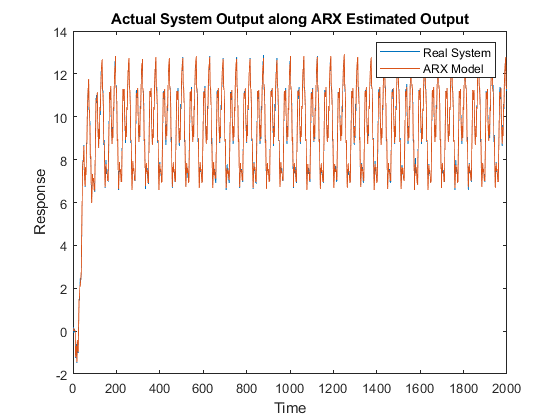

na = degree_based_on_Var;
nb = degree_based_on_Var;
p = na + nb;

U = arx_U_builder(na,nb,prbs_signal,y_out);

theta_hat = inv(U'*U)*U'*y_out;
y_hat = U*theta_hat;

t = (step_resp.TimeInfo.Start:proper_Ts:step_resp.TimeInfo.End);

figure(7)
plot(tspan,y_out,tspan,y_hat)
title("Actual System Output along ARX Estimated Output")
xlabel("Time")
ylabel("Response")
legend('Real System','ARX Model')

### >>> 1.8 - Real Order of the System using the Determinants

fprintf("===========================================================================================\n")

fprintf(">>> Let's try higher orders to see wether the determinant of the system ever zero or not.\n")

>>> Let's try higher orders to see wether the determinant of the system ever zero or not.


fprintf("    For so, run the algorithm from degree of 11 to 100.\n")

    For so, run the algorithm from degree of 11 to 100.


fprintf("===========================================================================================\n")

realDegree = false;
for degree=11:1:100
    na = degree;
    nb = degree;
    p = na + nb;

    U = arx_U_builder(na,nb,prbs_signal,y_out);

    theta_hat = inv(U'*U)*U'*y_out;
    y_hat = U*theta_hat;
    
    t = (step_resp.TimeInfo.Start:proper_Ts:step_resp.TimeInfo.End);

    [r2_arx, mse_arx] = rSQR(y_out, y_hat);

    detUTU = det(U'*U);

    fprintf(">>> Degree = %d : R2=%f | MSE=%f | det(UT.U)=%f | var=%f \n", degree, r2_arx, mse_arx, detUTU, variance)
    fprintf("-------------------------------------------------------------\n")

    if (detUTU < 1)
        fprintf("YEP ! The system real degree is %d.\n", degree)
        realDegree = true;
        break;
    end
end

>>> Degree = 11 : R2=0.998367 | MSE=0.007911 | det(UT.U)=192416147516438909978714618870848248340243395117056.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.998580 | MSE=0.006879 | det(UT.U)=385318705693384610246444616061248948566320883630604288.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.998689 | MSE=0.006350 | det(UT.U)=664561660710955795000140281213887035667021003692787630080.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.998777 | MSE=0.005923 | det(UT.U)=1050003253957598727938880983975628539507863896002144216547328.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.998879 | MSE=0.005428 | det(UT.U)=1527729495973817806135837434844659143451495416734479486289969152.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.998919 | MSE=0.005238 | det(UT.U)=1973158599833437402707475888330876030797568337867929752457120317440.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.998941 | MSE=0.005130 | det(UT.U)=2349139144705444967761436174168742378884641021157754276455136347815936.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.998949 | MSE=0.005090 | det(UT.U)=2665946747916811205753890584352735733929949098387533065560220851903660032.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.998964 | MSE=0.005017 | det(UT.U)=2965432929331652036825639068227110801899776141427223104602550363339005886464.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.998972 | MSE=0.004980 | det(UT.U)=3162302711932641209895590287095975151185897169533521953443344032867413624094720.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.998980 | MSE=0.004940 | det(UT.U)=3316319292048510234253527764435569632290229438256749110941384344164249339317714944.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.998982 | MSE=0.004931 | det(UT.U)=3389130870729679707992719965271460430743675746150046994629391715233494083728090071040.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.998986 | MSE=0.004911 | det(UT.U)=3278211194305734236661142528278934695744133958639584325048318271684917490814255206760448.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.998991 | MSE=0.004888 | det(UT.U)=2811766175977739838339198238676843182702623553535610064359967480671060716722082537191505920.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.998991 | MSE=0.004887 | det(UT.U)=1688116413181497066988234753335369089542565003973833079637361853243590510616819526597477400576.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.998992 | MSE=0.004883 | det(UT.U)=813238717650121468473568612885883151368298152387872439272069620325538279348097522817837704413184.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.998993 | MSE=0.004879 | det(UT.U)=336115302402484181541542065144067554258515633595367692918337342780213235717803985340999664974954496.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.998997 | MSE=0.004857 | det(UT.U)=62043535315407275823061036546523200263278407182660206616772190981708734850805270628442230755677962240.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.998998 | MSE=0.004853 | det(UT.U)=4383478802905857300199102725355554363110409844558222210906810702897181958052113396828322817548205686784.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.998998 | MSE=0.004851 | det(UT.U)=300693735913969083081787210055671892602912023887846701932642374720403326584168537314840147954763053400064.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.999005 | MSE=0.004820 | det(UT.U)=16031030082669060909988665771728389626348281133204019234789549773200815350288656676771763096458965282717696.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.999005 | MSE=0.004819 | det(UT.U)=656693694034601602362310810738564663040624363716066332740451694020503248510457892677161577645550658425716736.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.999005 | MSE=0.004818 | det(UT.U)=26781778881531455186467610097695422068602074831761498794960505951362144130066737850276185580688246419023200256.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.999011 | MSE=0.004789 | det(UT.U)=1080324221960989089501819671538028791320811890481658494464051089453053043334204614452084536483170359504592175104.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.999017 | MSE=0.004764 | det(UT.U)=43228127557480442275491895990989514161203987592310719886119854233931545633833620885384537903805263352501307965440.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.999017 | MSE=0.004761 | det(UT.U)=1705685411420668719630266938237288145598734171980659752127722843198208423902129826630696768109390492114775586111488.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.999018 | MSE=0.004756 | det(UT.U)=66571121825946492677009937167683090665035528682509263076551862696992101097011682318132407382843011109354074810613760.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.999019 | MSE=0.004752 | det(UT.U)=2581194975985712264133072337277027249575979399208744686513256044341427791437633711773790988650439977441684402552700928.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.999020 | MSE=0.004745 | det(UT.U)=99135778142999018462257987118810714709085476404497909416557284165533808223736510550737987230822524803296870802846121984.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.999021 | MSE=0.004744 | det(UT.U)=3788234538639105591127583553726157883758647118533512577870272078154907854576682734679368468976854124926300703614430085120.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.999021 | MSE=0.004741 | det(UT.U)=142118022528372376318420263138414725147888737204840729765513017781043508195537273342437640693567987865693224236144331325440.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.999021 | MSE=0.004741 | det(UT.U)=5270551993356096028122890695490772307454774466277502169934998851321496384047666012868975480994956930943304934516543832719360.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.999022 | MSE=0.004739 | det(UT.U)=195201075702008915778268996833448571798388162868522414236609250476452432665036962284321234072598549299007473235852238761492480.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.999023 | MSE=0.004734 | det(UT.U)=7135815459909006837146789656418212427070056721097387042048373274615319506300107025795669559394992527808541237836754276654776320.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.999029 | MSE=0.004702 | det(UT.U)=259998177787989233565839773225454225970311095163714522441883129890148243362661458198366495083313078413385249520100330107641528320.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.999029 | MSE=0.004701 | det(UT.U)=9341481546574301667337693222060238510791823512468624384051728829010377912176521417789678889057336674586253488149425784844997099520.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.999031 | MSE=0.004694 | det(UT.U)=332571797741729244506708200869276980393434007173979683317182149544199581559102063248180640316384190402787889876033541250042663272448.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.999039 | MSE=0.004657 | det(UT.U)=11770755996634137999875041084835267872616114989006941921056968167395568315998568295169341058105344695404141005462611824745994675814400.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.999039 | MSE=0.004654 | det(UT.U)=410260835368992477811470453686093948474402175994070186373794739838535483290583691707585767964771738543971295118678354105663585475624960.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.999040 | MSE=0.004652 | det(UT.U)=14128172769124111925636989848932946662373551523877653003480885970868048747975897625884252837746414958896314914661475054321426552464605184.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.999042 | MSE=0.004641 | det(UT.U)=483972264280619719439240816158517184326723272852850921521924094363299192594639260407984204300068543377340813953058537306800521819711340544.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.999043 | MSE=0.004635 | det(UT.U)=16454579902956781471210412761222674135473395551681052561102430934980826076234614351923536355071539669662488469346947875212835458919904051200.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.999044 | MSE=0.004631 | det(UT.U)=555967500306930799054588848103624054904343423090974864112273992105499817585079381812952067143303470247194232191045314770634286252671807520768.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.999045 | MSE=0.004626 | det(UT.U)=18665762311393195299197652585803915029477955083628604185754433177045111209805468211318227100078144453479903029778566061332672755188064262815744.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.999048 | MSE=0.004611 | det(UT.U)=624220920328122285718483704018363523114903023235277011978345206731384411767257125592086940089914096797105608074010426504576729830689254886342656.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.999052 | MSE=0.004593 | det(UT.U)=20711420451616402902021656365030440451987875531501421841074305282128255647947180500120138713500011174752502179770637767140957398219520159942443008.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.999054 | MSE=0.004581 | det(UT.U)=681350465167920795530292853778881718123992364076008951589954414566857215652728810130992731304802203113964504350307942542048752659196390314206035968.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.999055 | MSE=0.004578 | det(UT.U)=22234865329676852965218632379376013581463934538057674147624456493209919948760698945755663552207166808952310698833632304760993324532871445154055061504.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.999055 | MSE=0.004578 | det(UT.U)=720770779062203720071080131534537621757727251029674152323399537375914717780290276668303049805337578162389738565742329246442985195483293875294911332352.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.999061 | MSE=0.004546 | det(UT.U)=23327204722620363827897086910013526134723384058368891686914185418989718425127928685743901554386669173978491172983013537696327397861157233572405758132224.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.999061 | MSE=0.004546 | det(UT.U)=746323286814132996759066683933682112966309077081522817514770214708551457974385181753389771485413665052489831048235581193796244823341198952019582976524288.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.999067 | MSE=0.004521 | det(UT.U)=23704298972445372411158115683039637806713574822209697134637842117535651871774457834862212053397957599672416903396417852599084529488020283120581341052141568.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.999071 | MSE=0.004501 | det(UT.U)=742284651765816365829643252135320353757891073532106902983996237284821854876479394354765349339807198006681048806236384589753160719800075093280634379666718720.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.999072 | MSE=0.004495 | det(UT.U)=23118319106928684202086697122503823477500209205226668893368376027351075127610568927949231503658261241144836831398219056251230845584516712077877460686679834624.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.999073 | MSE=0.004491 | det(UT.U)=718197494712363921692098412347577332407680672398137352426500512573740214911989987082042105925106486578291446845712772963467077472421962229732020270135448174592.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.999073 | MSE=0.004489 | det(UT.U)=22188739072115761815554787014824681653495724328263476338336142017499395221724731569159067175659668952187221910880094937764133522318627427799835659664353082212352.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 67 : R2=0.999088 | MSE=0.004415 | det(UT.U)=684383755422509924203494300854721312742939527203607491653040383251059507525620273035547827413337487467871254958362912163390472570675040968325185555124182088417280.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 68 : R2=0.999089 | MSE=0.004412 | det(UT.U)=20730315956771317518465830942713584659042096907011005994934559366807376932174119740733553731657666790003565501893673036147719075205613632007357050610865572566532096.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 69 : R2=0.999090 | MSE=0.004409 | det(UT.U)=624378669850215160003791359813797462955045953098493777554264300709212490062180057190880605856169889091184470080953552034145095648158362700490552334105920527239479296.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 70 : R2=0.999095 | MSE=0.004384 | det(UT.U)=18737458012421644753993119569578733981754112623121780033020931936361294515722722303891290023517469095030561781076287767691219773955584498642120165512534224486075990016.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 71 : R2=0.999099 | MSE=0.004364 | det(UT.U)=557646021201890363854979654500026043156386791768295329162405188195511457675361385555404412120760315928662434981294127431298049523368481897047134465833300082414992752640.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 72 : R2=0.999100 | MSE=0.004362 | det(UT.U)=16489878364023422913725114372573446091030527948482299518567428851439673693273082580317327666355698316730544900885069689539865852137485223007487761825674377725297565892608.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 73 : R2=0.999101 | MSE=0.004357 | det(UT.U)=485032020638191103146074740914505936235342135616591834373643099764683973547308314088328052682842374125438048729664061170551039059983444283409638767725428748202230258073600.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 74 : R2=0.999102 | MSE=0.004347 | det(UT.U)=14228855836795554186938166986262788185921483065551587574496354842316016297353744552970017499812325819466088740390583389537194946947131621071950639973661143527020293492047872.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 75 : R2=0.999107 | MSE=0.004324 | det(UT.U)=416017361475817895789618652514063895731906041431915063339405033870900061150099875947288972937751670860399959824203527443343743339488700423964740278193732762253650683345502208.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 76 : R2=0.999109 | MSE=0.004316 | det(UT.U)=12092818638318084134417919849190910705371569365307160873803324619624887624170294326609800068183267741413756250870779879765762065416924372655388104733114155380498184379599683584.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 77 : R2=0.999110 | MSE=0.004311 | det(UT.U)=350578287955420726286354879198413247522629528613910499918837447536831476789732725292151123662148096152412146800979091067487848450301257264111359893022050485919405632339492995072.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 78 : R2=0.999112 | MSE=0.004302 | det(UT.U)=10147921686995962730050765176380786625118930041254881745679952947219354063850602966712192467812452179044891876576364912802877272632792684162337409913385048142917485155213239123968.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 79 : R2=0.999114 | MSE=0.004293 | det(UT.U)=292974599735831082065625831197589526805128082096856980330069692519793115493435081928373655422494453026720360669793104302898531822783554084278736891453187096524945040870927316811776.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 80 : R2=0.999114 | MSE=0.004290 | det(UT.U)=8403248973938154083936311423368178696716559388902009142726074616889213202154903232947365075408991395662143613816406112743983637988356268821603684733484115806713004470182852668948480.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 81 : R2=0.999119 | MSE=0.004266 | det(UT.U)=240034612698685988128788609501126082969046325998702502888962240604438013122650231890607954830361324657013650482327068029261451682790401839281194690705993151039993030239592385030914048.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 82 : R2=0.999120 | MSE=0.004260 | det(UT.U)=6813796526531479391673472221710295321079564281332212143374066923456442610668023141346341281877876452845483305938031229523636970721967627914087703284623387411066829464331709317740756992.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 83 : R2=0.999121 | MSE=0.004257 | det(UT.U)=191330542942140371893278525050209814606307215472340250927255015694743853550765188867241836160674562348748803962141153682903520739017012062659241231344046173893151275173955667268468736000.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 84 : R2=0.999122 | MSE=0.004254 | det(UT.U)=5346115294259721110532553427558288281939330110954223554271586537289215956830417245909467189562276609699713924071486529723218192208353587956484339985864740547834708621017202438271341166592.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 85 : R2=0.999126 | MSE=0.004233 | det(UT.U)=149096275544730619557384010076678674799491091886976013578553387331395973519516710053766590047978873388552161573151449291357161732804960459031841522756790410329764826326920768090746273136640.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 86 : R2=0.999127 | MSE=0.004230 | det(UT.U)=4104630684781460102107725609867953395574338825441996065911615763772277400801320106710732074776009318975807122614805767384056949821373568178062556589786073064626152614817773107394874150223872.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 87 : R2=0.999131 | MSE=0.004210 | det(UT.U)=112541422455042001833876875654220851619001836452280896901254425989166269390959716574229573536158797492276479129247237781851301287585407876567340146217841622194091843858667099402440793160417280.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 88 : R2=0.999131 | MSE=0.004207 | det(UT.U)=3065933601296875181821699503054701020414461318907047260119607709090925725465177917282919830962294054787414877285825488670191895230526190403146960046434509546354656743060064029382404643590504448.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 89 : R2=0.999133 | MSE=0.004200 | det(UT.U)=83023636196326995996736969085577974755518937276230036241354116461373686457436633829519692054397529998197022124435593818294520423778927465869553671553311778498864490240920577463477004182721921024.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 90 : R2=0.999134 | MSE=0.004194 | det(UT.U)=2241602442772615163429855112561698874715701218181572123979840782310966738117065322725616236667840915748973975032345193902480714011263991857303034061871696000683192121075675330377176675085107331072.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 91 : R2=0.999143 | MSE=0.004152 | det(UT.U)=60345821354051361127166571605074898946803410606035518113629255342977528962521427991728055334221542447776891151951436024894296940546724893601776358840305566028730182894540877335748216146201222840320.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 92 : R2=0.999145 | MSE=0.004140 | det(UT.U)=1601071623364314696244230532778507960947431671391102573062737583235441658684446259147897864878511650217479184303039870600187944491506317561170683899219485612669417616661427263679034594953591569514496.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 93 : R2=0.999147 | MSE=0.004133 | det(UT.U)=42297315933242693398606661262235432119219611895584655217125745919419578694810126727616594586541269534874511589768758618934272144549179793481124898859561971471335828526250207835757412617157942834102272.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 94 : R2=0.999147 | MSE=0.004131 | det(UT.U)=1114239168671212753217035085809746827026549151950525974507595931873642272100443232736032900148704349486273159262737510045244938635938791227703506980969547513171090935708250322070104907964153685442822144.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 95 : R2=0.999149 | MSE=0.004123 | det(UT.U)=29299222928355992839739730936570297886521042772608958831981503719121040590300664879624680935996862407856272753228676776214065353908937628112042326460990741653670663266657342367815307752172557812971339776.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 96 : R2=0.999150 | MSE=0.004118 | det(UT.U)=765825284701071305074939312804615452144294761244864726777051701409722417285809397597745706720096697966973178849502721464347883001128553041816737378062285869431870862913021358292434980168472666677874524160.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 97 : R2=0.999151 | MSE=0.004113 | det(UT.U)=19981623596207235360162577716440251416582039332531075964717542327142162978625026181895442182315974704428783841008696482457057235573883333242895448576473248200443652750051891558836531412315767744021424766976.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 98 : R2=0.999153 | MSE=0.004101 | det(UT.U)=519661812647585862692825742808548050196392680196174907554272687137497130566458731354048611674247666168983754513219498560609428154029446989741297196729028820010820229945188706886226409668260146744397603536896.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 99 : R2=0.999157 | MSE=0.004085 | det(UT.U)=13458030272772235828539185431772418169845327195840357663648638890736909152519608813215540876677006434083106073168484601656606240892614573387083143566448591502470100574318244917368902545233561673984046522171392.000000 | var=0.009660 


-------------------------------------------------------------


>>> Degree = 100 : R2=0.999163 | MSE=0.004056 | det(UT.U)=347028001505049182956129195843161121972489983674138199594244394011926880475362964165659804377696664233413819348661187606718438934236336862121533975271429474825090004214242368053511027985545398862643898452279296.000000 | var=0.009660 


-------------------------------------------------------------


if ~realDegree
    fprintf(">>> No! Not until degree of 100. \n")
end

>>> No! Not until degree of 100. 


fprintf("=================================================================\n")

### >>> 1.9 - Comparing  Approaches

>>> Both Variance-based and MSE-based degree extraction approaches suggested a proper order of 5 for the given system while the R2-based stated that the model would be good enough with the order of 4.